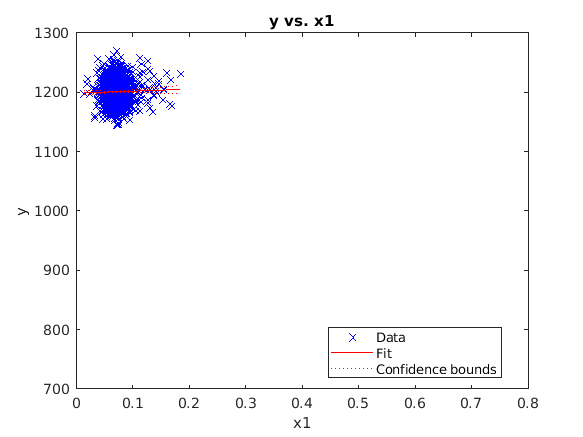

ans = 19.9794

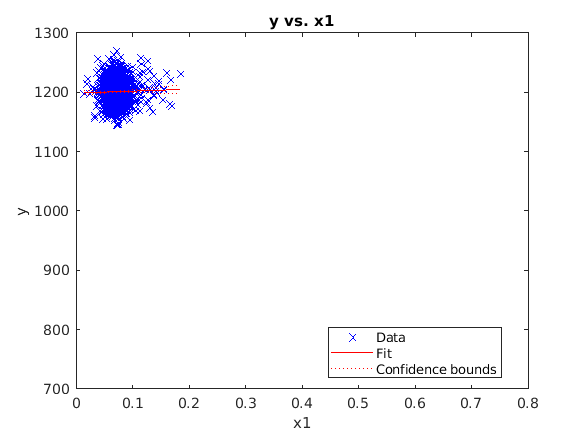

ans = 19.9793

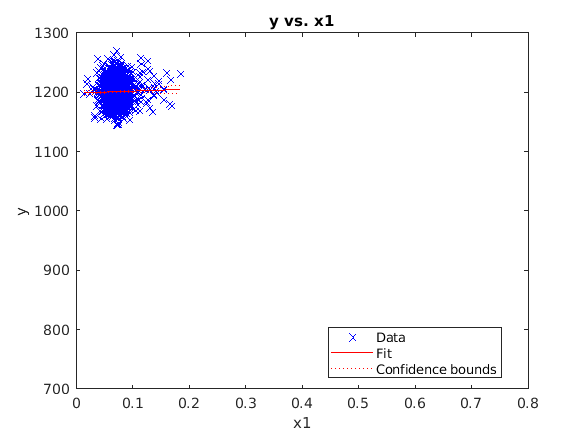

ans = 19.9790

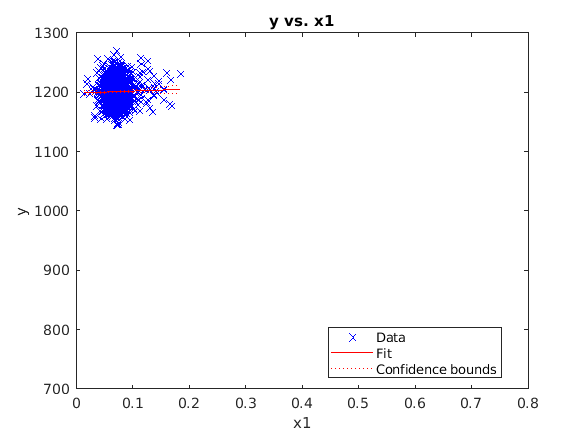

ans = 19.9785

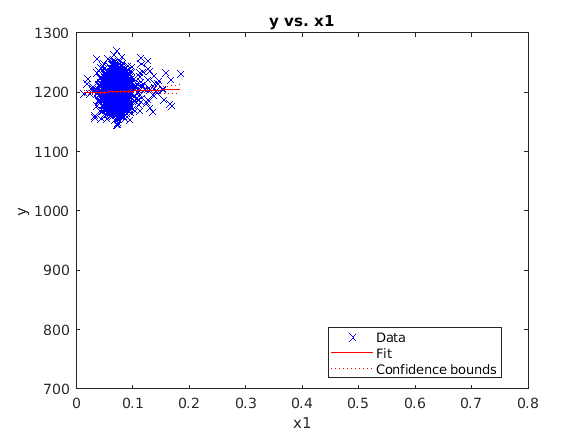

ans = 19.9776

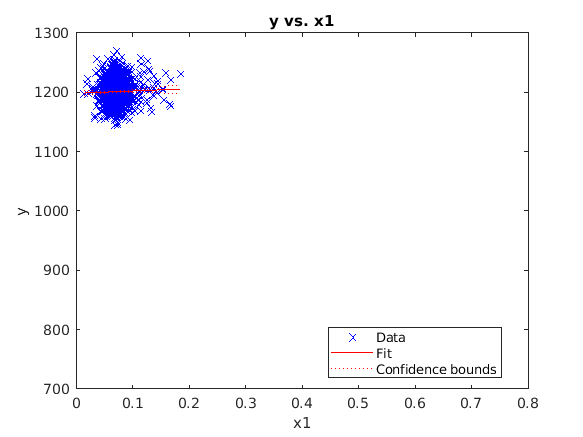

ans = 19.9762

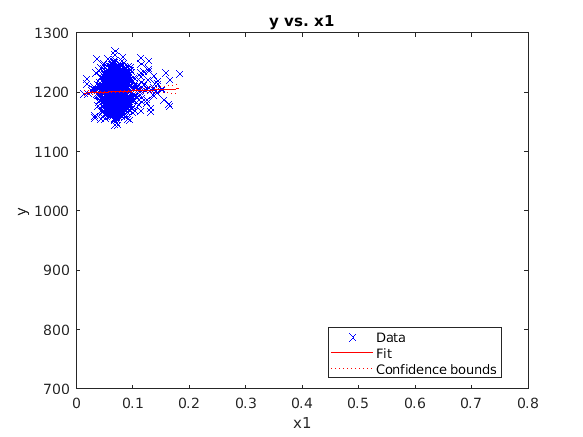

ans = 19.9745

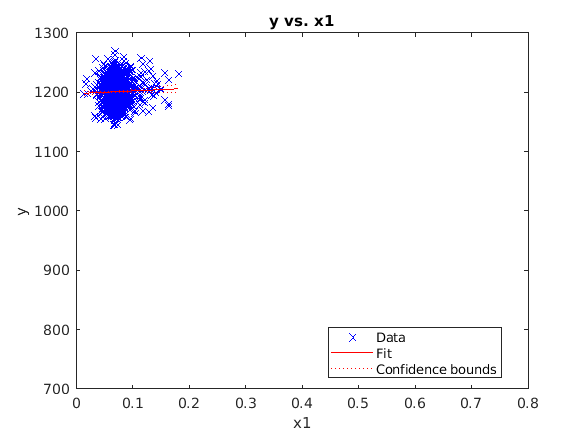

ans = 19.9728

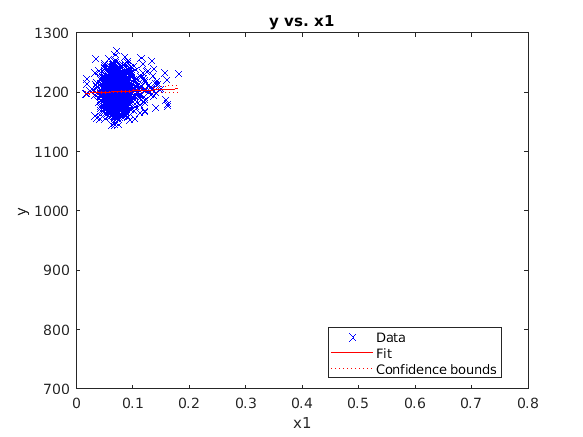

ans = 19.9720

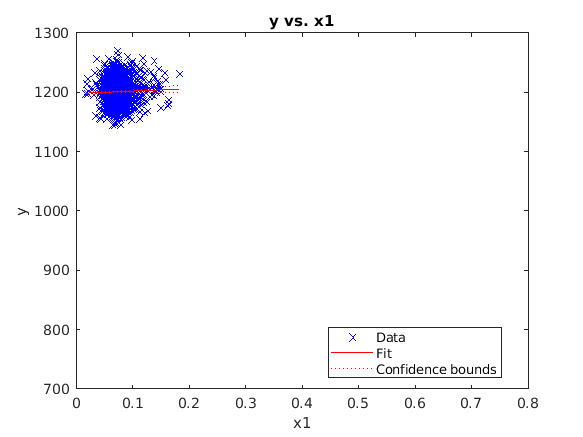

ans = 19.9721

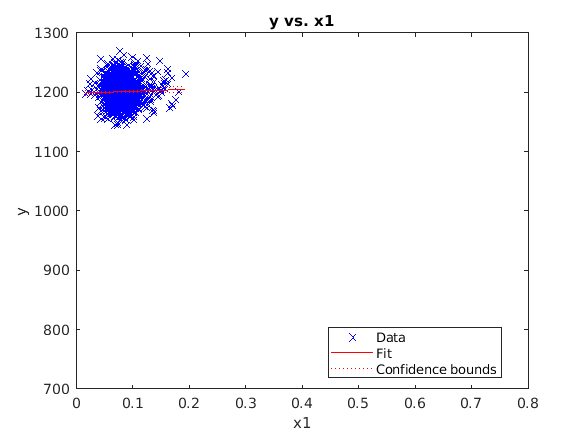

ans = 19.9739

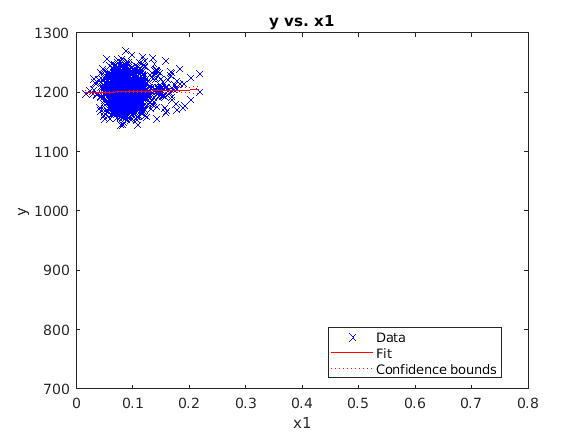

ans = 19.9771

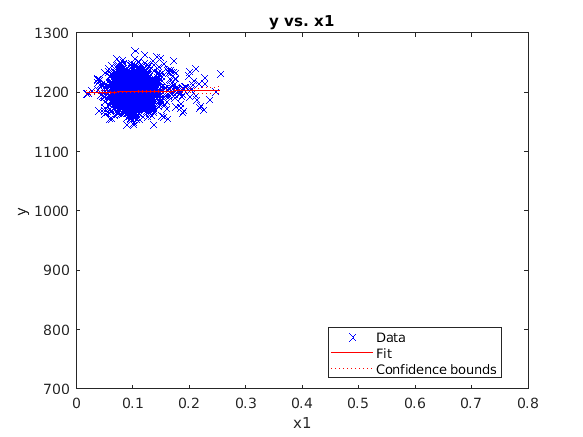

ans = 19.9809

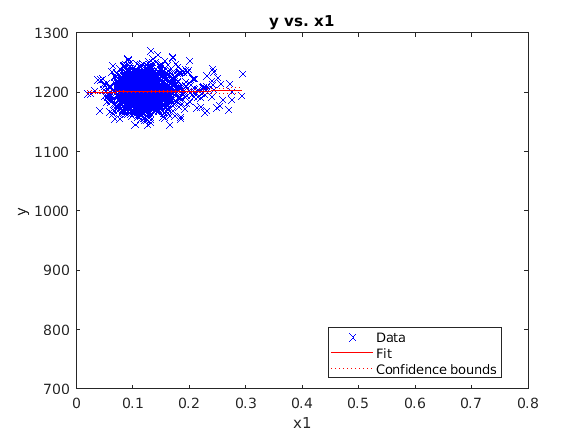

ans = 19.9838

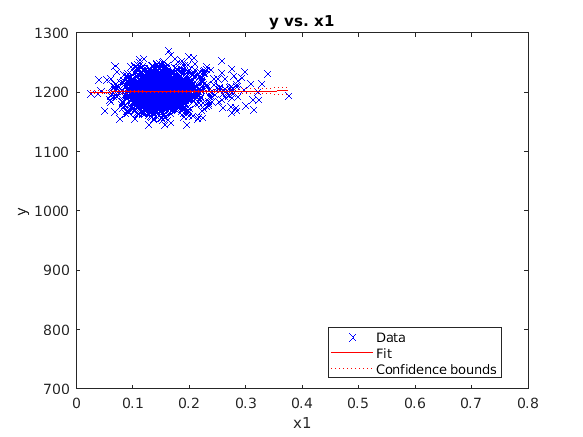

ans = 19.9854

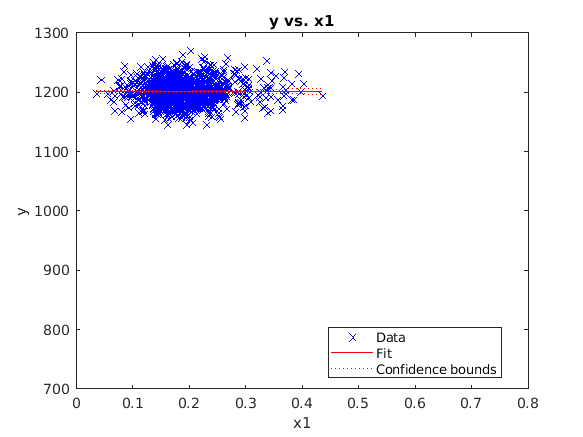

ans = 19.9861

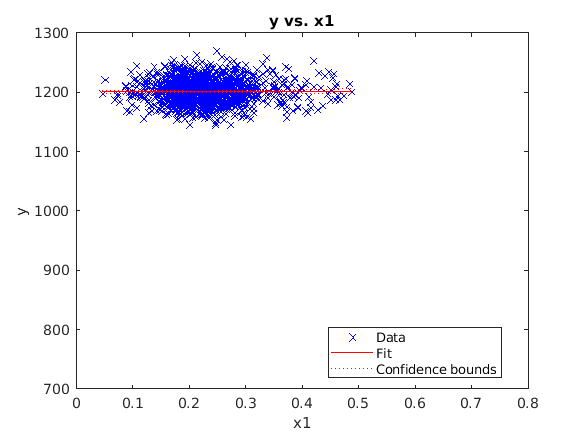

ans = 19.9864

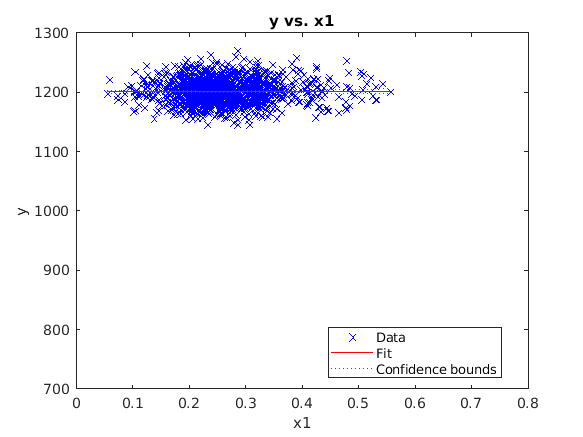

ans = 19.9865

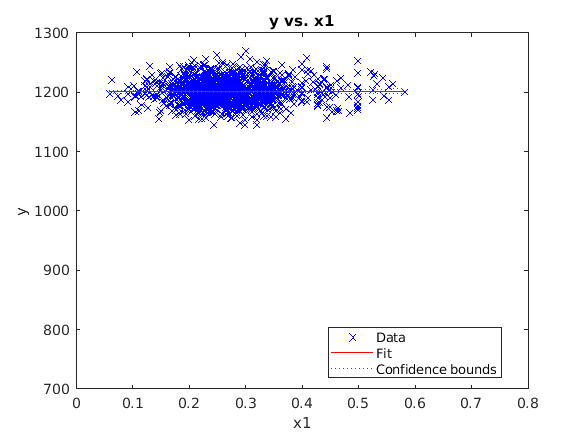

ans = 19.9865

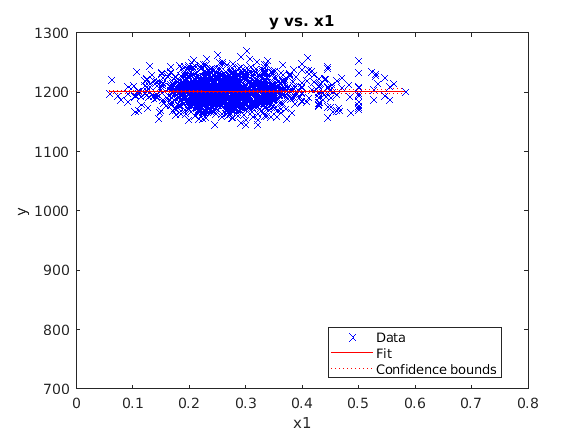

ans = 19.9865

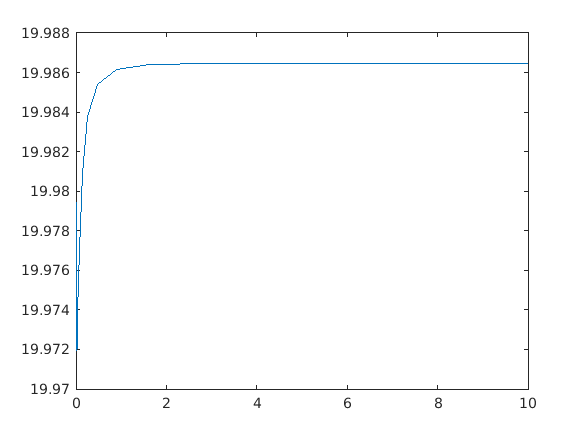

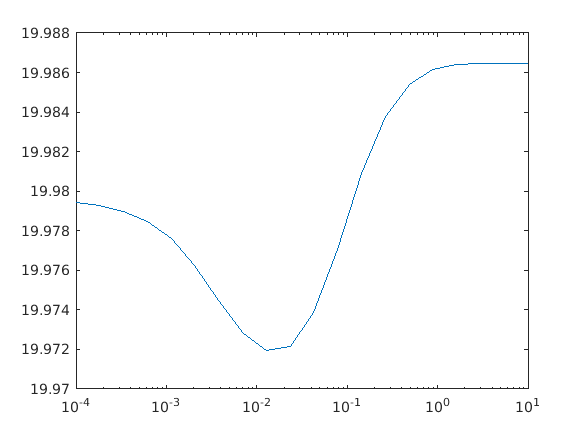

% this code was used to analyse synthetic data that was generated 
% by sampling from three different gaussian distributions. 
% This was done for purposes of debugging, and to verify if there will 
% a significant slope with "ideal/synthetic" data. 

clear all;
clc;

target_file = readmatrix("synthetic-target-long-01.csv");
%trial_file = readmatrix("trial-full-01.csv");
rt_file = readmatrix("synthetic-bad-long-02.csv");
%graph_file = readmatrix("graph-full-01.csv");

RT = [];
trial = [];
target = [];
ID = []; 
log_trial = [];
mat_size = size(rt_file);

for i = 1:mat_size(1)
    this_RT = transpose(rmmissing(rt_file(i, :)));
    RT = [RT; this_RT];
    trial = [trial; transpose(1:length(this_RT))];
    log_trial = [log_trial; log(transpose(1:length(this_RT)))];
    target = [target; transpose(rmmissing(target_file(i, :)))];
    ID = [ID; i*ones(size(this_RT))];
end

pretest_table = table(ID, trial, log_trial, target, RT);
pretest_table.target = categorical(pretest_table.target);
pretest_table.ID = categorical(pretest_table.ID);

residual_intercept = pretest_table.RT;


beta_values = logspace(-4, 1, 20);

subject = [1,2,3,4,5,6, 7, 8, 10, 11];
results = [];


for subj = subject
    x = pretest_table.target(pretest_table.ID == categorical(subj));
    r = residual_intercept(pretest_table.ID == categorical(subj));
    r = r(2:end);
    errors = [];
    for b = beta_values
        belief = zeros([15, length(x)]);
        for t = 1:length(x)
            for i = 1:t
                belief(x(i), t) = belief(x(i), t) + prob(t - i, b);
            end
        end
        a = zeros([length(x), 1]);
        n = zeros([15, 15]);
        
        for t = 1:length(x)-1
            for i = 1:15
                n(i, x(t+1)) = n(i, x(t+1)) + belief(i, t);
            end
            a(t+1) = n(x(t), x(t+1))/sum(n(x(t), :));
%{
            if mod(t, 10) == 0
                figure;
                plot(a(t-9:t));
                figure;
                plot(r(t-9:t));
                figure;
                heatmap(belief(:, max(1, t-40):t));
                figure;
                heatmap(n);
                disp(x(t-9:t));
                disp("one");
            end
            %}
        end
        a = a(2:end);
        model = fitlm(a(150:end), r(150:end));
        figure;
        plot(model);
        ylim([700, 1300])
        xlim([0, 0.8])
        model.RMSE
        errors = [errors, model.RMSE];
    end
    figure;
    plot(beta_values, errors);
    save('beta_error'+string(subj)+'.mat', "errors");
    saveas(gcf, 'beta-'+string(subj)+'.png');
    figure; 
    semilogx(beta_values, errors);
    saveas(gcf, 'semi-beta-'+string(subj)+'.png');
    close all;
end